% extended kalman filter example 1
% tracking of an airplane
% states = (distance, velocity, altitude) = (x, xdot, y)
% measures = (range, bearing) = (slant, elevation angle) = (r, etha)

### **Clearing**

clear variables; close all; clc;
addpath('../utilities');
rng(1)

### **Model**

% number of states, usually n
% position (distance), velocity and altitude
dim_x = 3;

% number of measures, usually m
% range and bearing sensor: only range now
dim_z = 1;

% time step [s]
dt = 0.05;

% std of the two sensors
slant_range_std = 5;

% aircraft information in the plane
ac_pos = [0, 1000];
ac_vel = [100, 0];
ac_std = 0.01;

% radar information
r_pos = [0, 0];

% process noise covariance
Q(1:2,1:2) = [0.25*dt^4 0.5*dt^3; 0.5*dt^3 dt^2] * 0.1;
Q(3,3) = 0.1;

% measure noise covariance
R = diag(slant_range_std^2);

% (non linear) measurement function
h = @(x) sqrt(x(1, :).^2 + x(3, :).^2);

% (non linear) state transition function
f = @(x) [1, dt, 0;0, 1, 0;0, 0, 1] * x;

### **Initial conditions**

% initil state (mean)
x0 = [-100, 200, 2000]';

% initial belief of the state (covariance)
P0 = diag([100^2, 100^2, 100^2]);

### **Filter settings**

% seconds of measures
endtime = 30;

% number of measures
n = endtime/dt + 1;

% data structures
x_posterior = zeros(dim_x, n);
zs = zeros(dim_z, n);
xs = zeros(dim_x, n);
P_posterior = cell(1, n);

### **Filter initialization**

% 1. Initialize the state of the filter
x = x0;

% 2. Initialize our belief in the state
P = P0;

### **Filtering (simulation of aircraft and sensors measures)**

for tt = 1 : n   
    % simulate aircraft position in the plane
    ac_pos = ac_pos + ac_vel * dt + randn(1, 2) .* [ac_std 0];
    
    % linearized state transition function
    F = [1, dt, 0;0, 1, 0;0, 0, 1];

    % predict step:
    % 1. Use process model to predict state at the next time step (what we expect)
    % (using non linear function)
    x = f(x);
    % 2. Adjust belief to account for the uncertainty in prediction (using linearized function) 
    P = F*P*F' + Q;

    % linearized measurement function
    H = [x(1, :)/sqrt(x(1, :).^2 + x(3, :).^2) 0 x(3, :)/sqrt(x(1, :).^2 + x(3, :).^2)];
    
    % update step:
    % 1. Get a measurement and associated belief about its accuracy
    % simulate new radar measure (range; bearing)
    z = radar_simulator(r_pos, slant_range_std, 0, ac_pos);
    % only range
    z = z(1);
    % 2. Compute residual between estimated state and measurement
    e = z - h(x);
    % 3. Compute scaling factor based on whether the measurement or prediction is more accurate
    K = P*H' / (H*P*H' + R);
    % 4. set state between the prediction and measurement based on scaling factor
    x = x + K*e;
    % 5. update belief in the state based on how certain we are in the measurement
    % P = P - K*H*P;
    % Joseph equation to reduce numeric errors
    P = (eye(dim_x)-K*H)*P*(eye(dim_x)-K*H)' + K*R*K';
    
    % saving
    xs(:, tt) = [ac_pos(1) ac_vel(1) ac_pos(2)]';    
    zs(:, tt) = z;   
    x_posterior(:, tt) = x;
    P_posterior{tt} = P;   
end

### **Matlab filter**

% filter modeling and initialization
ekf = extendedKalmanFilter(f, h, x0);
ekf.State = x0;
ekf.StateCovariance = P0;
ekf.StateTransitionFcn = f;
ekf.StateTransitionJacobianFcn = @(x) F;
ekf.ProcessNoise = Q;
ekf.MeasurementFcn = h;
ekf.MeasurementJacobianFcn = @(x) [x(1, :)/sqrt(x(1, :).^2 + x(3, :).^2) 0 x(3, :)/sqrt(x(1, :).^2 + x(3, :).^2)];
ekf.MeasurementNoise = R;

% data structures
x_prior_matlab = zeros(dim_x, n);
P_prior_matlab = cell(1, n);
x_posterior_matlab = zeros(dim_x, n);
P_posterior_matlab = cell(1, n);
 
for tt = 1:n
    % predict
    [x, P] = predict(ekf);
    
    % saving
    x_prior_matlab(:, tt) = x;
    P_prior_matlab{tt} = P;
    
    % update
    [x, P] = correct(ekf, zs(:, tt));
    
    % saving
    x_posterior_matlab(:, tt) = x;
    P_posterior_matlab{tt} = P;  
end

### **Plots**

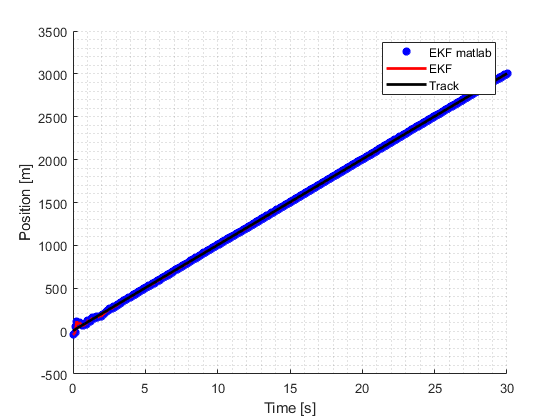

time = 0 : dt : endtime;

% Tracking of position comparison
figure; hold on; grid minor;
set(gcf, 'DefaultLineLineWidth', 2);
plot(time, x_posterior_matlab(1,:), 'b*');
plot(time, x_posterior(1,:), 'r');
plot(time, xs(1,:), 'k');
xlabel('Time [s]'); ylabel('Position [m]'); legend( 'EKF matlab', 'EKF', 'Track');

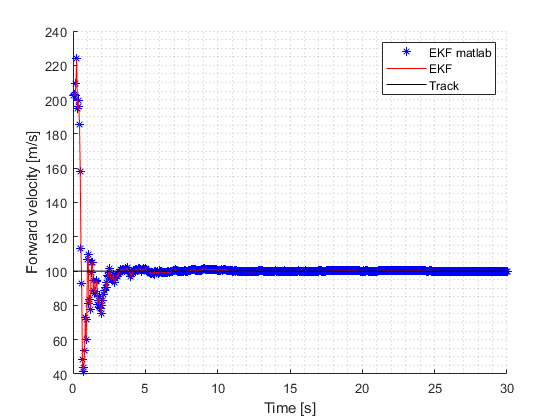

% Tracking of forward velocity comparison
figure; hold on; grid minor;
plot(time, x_posterior_matlab(2, :), 'b*');
plot(time, x_posterior(2, :), 'r');
plot(time, xs(2, :), 'k');
xlabel('Time [s]'); ylabel('Forward velocity [m/s]'); legend( 'EKF matlab', 'EKF', 'Track');

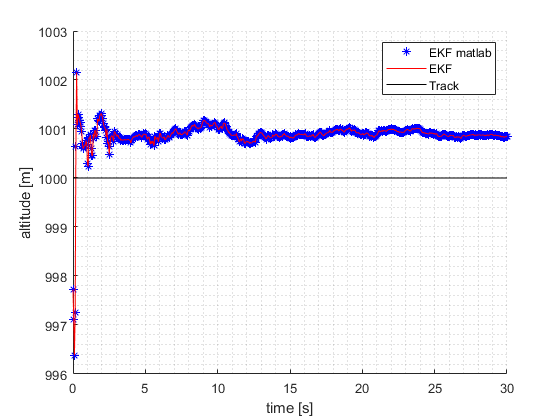

% Tracking of altitude comparison
figure; hold on; grid minor;
plot(time, x_posterior_matlab(3,:), 'b*');
plot(time, x_posterior(3,:), 'r');
plot(time, xs(3,:), 'k');
xlabel('time [s]'); ylabel('altitude [m]'); legend( 'EKF matlab', 'EKF', 'Track');